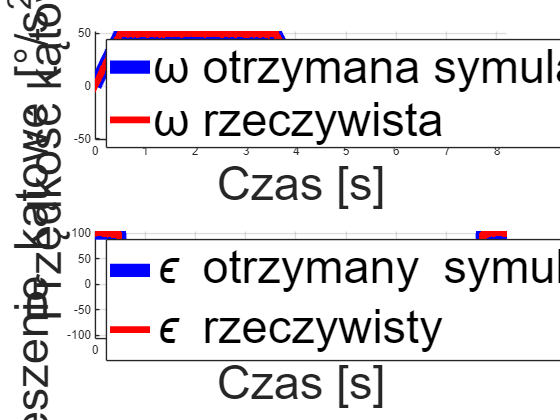

clc; clear;

ur3 = loadrobot("universalUR3", "DataFormat", "row", "Gravity", [0 0 -9.81]);

v_max = deg2rad(50);
a_max = deg2rad(100);
dt = 0.01;

q_home = [-0, -90, 0, -90, 0, -0.000]*pi/180;
q_end  = [0, -90, 0, -90, 180, -0.000]*pi/180;

q_home = q_home(:); 
q_end = q_end(:);   

dq = abs(q_end - q_home);
t_total_joint = zeros(6,1);

for i = 1:6
    if dq(i) < 1e-4
        t_total_joint(i) = 0.5;
        continue;
    end
    t_acc = v_max / a_max;
    d_acc = 0.5 * a_max * t_acc^2;

    if dq(i) < 2*d_acc
        t_total_joint(i) = 2 * sqrt(dq(i) / a_max);
    else
        t_total_joint(i) = 2*t_acc + (dq(i) - 2*d_acc)/v_max;
    end
end

trajTime = max(t_total_joint);

nSteps = ceil(trajTime / dt);
T_vec = linspace(0, trajTime, nSteps);
[qt1, qd1, qdd1] = trapveltraj([q_home, q_end], nSteps, 'AccelTime', v_max/a_max, 'EndTime', trajTime);
[qt2, qd2, qdd2] = trapveltraj([q_end, q_home], nSteps, 'AccelTime', v_max/a_max, 'EndTime', trajTime);

q_traj = [qt1'; qt2'];
qd_traj = [qd1'; qd2'];
qdd_traj = [qdd1'; qdd2'];
T_full = linspace(0, 2*trajTime, 2*nSteps);

x = 4.09499;
[~, k] = min(abs(T_full - x));
qdd_traj(k,5) = qdd_traj(k-1,5);

TCP_pos = zeros(2*nSteps, 6);
for i = 1:2*nSteps
    T = getTransform(ur3, q_traj(i,:), 'tool0');
    TCP_pos(i,1:3) = tform2trvec(T);
    TCP_pos(i,4:6) = tform2eul(T);
end

TCP_vel = [zeros(1,6); diff(TCP_pos)/dt];
TCP_acc = [zeros(1,6); diff(TCP_vel)/dt];

M = csvread('3512_ums.csv', 1,0);

idxB = 1; idxE = length(M);

M = M(idxB:idxE, :);

VarNames = {'Id','SessionId','aX','aY','aZ','gX','gY','gZ','mX','mY','mZ','Thermometer','Barometer','Trigger'};
SDLData = cell2struct(num2cell(M, 1), VarNames,2);

figure;
subplot(2,1,1)
hold on;
plot(T_full, qd_traj(:,5)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-4.83), SDLData.gY, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 8.2]); 
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 35);
hold off;

subplot(2,1,2)
hold on;
plot(T_full, (qdd_traj(:,5))*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id(1:650)/100-4.83), -SDLData.aY(1:650), 'Color', [1 0 0], 'LineWidth', 5);
plot((SDLData.Id(650:1000)/100-4.83), SDLData.aY(650:1000), 'Color', [1 0 0], 'LineWidth', 5);
plot((SDLData.Id(1000:1400)/100-4.83), -SDLData.aY(1000:1400), 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 8.2]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 35);
hold off;


offset = 483;
omega_ref = qd_traj(:,5) * 180/pi;
omega_meas = SDLData.gY;

omega_meas_shifted = omega_meas(offset+1:end);

N_ref = length(omega_ref);
N_meas = length(omega_meas_shifted);
N = min(N_ref, N_meas);

omega_ref = omega_ref(1:N);
omega_meas_shifted = omega_meas_shifted(1:N);

I_omega = mean(abs(omega_ref - omega_meas_shifted));

fprintf('Wartość funkcji celu I(ω): %.6f [°/s]\n', I_omega);

Wartość funkcji celu I(ω): 0.689947 [°/s]



a_ref = qdd_traj(:,5) * 180/pi;
a_meas = -SDLData.aY;
a_meas(650:1000) = -abs(a_meas(650:1000));

a_meas_shifted = a_meas(offset:end);

N_ref = length(a_ref);
N_meas = length(a_meas_shifted);
N = min(N_ref, N_meas);

a_ref = a_ref(1:N);
a_meas_shifted = a_meas_shifted(1:N);

valid_idx = (a_meas_shifted ~= 0) & (a_ref ~= 0);

a_ref_valid = a_ref(valid_idx);
a_meas_valid = a_meas_shifted(valid_idx);

if isempty(a_ref_valid)
    warning('Brak próbek spełniających warunek a_ref ≠ 0 oraz a_meas ≠ 0.');
    I_acc = NaN;
else
    I_acc = mean(abs(a_ref_valid - a_meas_valid));
end

fprintf('Wartość funkcji celu I(a): %.6f [°/s^2]\n', I_acc);

Wartość funkcji celu I(a): 1.537584 [°/s^2]



I_omega_t = abs(omega_ref - omega_meas_shifted);
time_vec = T_full(1:N);
I_acc_t = abs(a_ref - a_meas_shifted);
I_acc_t_valid = I_acc_t;
I_acc_t_valid(~valid_idx) = NaN;

figure;
subplot(2,2,1)
hold on;
plot(T_full, qd_traj(:,5)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-offset/100), SDLData.gY, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 8.18]); 
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 20);
set(gca, 'FontSize', 35)
hold off;

subplot(2,2,3)
hold on;
plot(T_full, (qdd_traj(:,5))*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id(1:650)/100-4.83), -SDLData.aY(1:650), 'Color', [1 0 0], 'LineWidth', 5);
plot((SDLData.Id(650:1000)/100-4.83), SDLData.aY(650:1000), 'Color', [1 0 0], 'LineWidth', 5);
plot((SDLData.Id(1000:1400)/100-4.83), -SDLData.aY(1000:1400), 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 8.18]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 20);
set(gca, 'FontSize', 35)
hold off;

subplot(2,2,2)
plot(time_vec, I_omega_t, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 30);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
legend('Rozbieżność ω', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

set(gca, 'FontSize', 35)
xlim([0 8.18]);

subplot(2,2,4)
I_acc_plot = I_acc_t_valid;
I_acc_plot(isnan(I_acc_plot)) = 0;
plot(time_vec, I_acc_plot, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 35);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
legend('Rozbieżność \epsilon', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

xlim([0 8.18]);
set(gca, 'FontSize', 35)

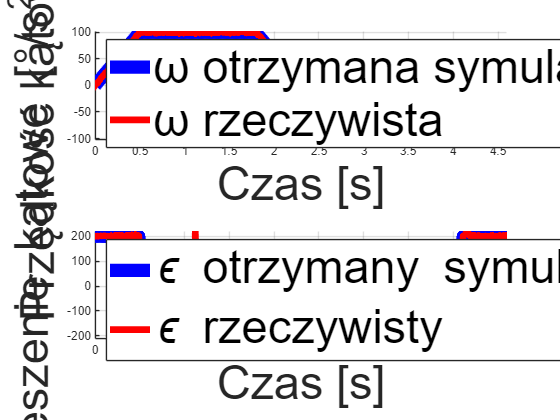

ur3 = loadrobot("universalUR3", "DataFormat", "row", "Gravity", [0 0 -9.81]);

v_max = deg2rad(100);
a_max = deg2rad(200);
dt = 0.01;

q_home = [-0, -90, 0, -90, 0, -0.000]*pi/180;
q_end  = [0, -90, 0, -90, 180, -0.000]*pi/180;

q_home = q_home(:); 
q_end = q_end(:);   

dq = abs(q_end - q_home);
t_total_joint = zeros(6,1);

for i = 1:6
    if dq(i) < 1e-4
        t_total_joint(i) = 0.5;
        continue;
    end
    t_acc = v_max / a_max;
    d_acc = 0.5 * a_max * t_acc^2;

    if dq(i) < 2*d_acc
        t_total_joint(i) = 2 * sqrt(dq(i) / a_max);
    else
        t_total_joint(i) = 2*t_acc + (dq(i) - 2*d_acc)/v_max;
    end
end

trajTime = max(t_total_joint);

nSteps = ceil(trajTime / dt);
T_vec = linspace(0, trajTime, nSteps);
[qt1, qd1, qdd1] = trapveltraj([q_home, q_end], nSteps, 'AccelTime', v_max/a_max, 'EndTime', trajTime);
[qt2, qd2, qdd2] = trapveltraj([q_end, q_home], nSteps, 'AccelTime', v_max/a_max, 'EndTime', trajTime);

q_traj = [qt1'; qt2'];
qd_traj = [qd1'; qd2'];
qdd_traj = [qdd1'; qdd2'];
T_full = linspace(0, 2*trajTime, 2*nSteps);

x = 2.29499;
[~, k] = min(abs(T_full - x));
qdd_traj(k,5) = qdd_traj(k-1,5);

TCP_pos = zeros(2*nSteps, 6);
for i = 1:2*nSteps
    T = getTransform(ur3, q_traj(i,:), 'tool0');
    TCP_pos(i,1:3) = tform2trvec(T);
    TCP_pos(i,4:6) = tform2eul(T);
end

TCP_vel = [zeros(1,6); diff(TCP_pos)/dt];
TCP_acc = [zeros(1,6); diff(TCP_vel)/dt];



M = csvread('3522_ums.csv', 1,0);

idxB = 1; idxE = length(M);
M = M(idxB:idxE, :);

VarNames = {'Id','SessionId','aX','aY','aZ','gX','gY','gZ','mX','mY','mZ','Thermometer','Barometer','Trigger'};
SDLData = cell2struct(num2cell(M, 1), VarNames,2);

figure;
subplot(2,1,1)
hold on;
plot(T_full, qd_traj(:,5)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-3.53), SDLData.gY, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 4.6]); 
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 35);
hold off;

subplot(2,1,2)
hold on;
plot(T_full, (qdd_traj(:,5))*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id(1:500)/100-3.53), -SDLData.aY(1:500), 'Color', [1 0 0], 'LineWidth', 5);
plot((SDLData.Id(500:700)/100-3.53), SDLData.aY(500:700), 'Color', [1 0 0], 'LineWidth', 5);
plot((SDLData.Id(700:900)/100-3.53), -SDLData.aY(700:900), 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 4.6]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 35);
hold off;


offset = 353;
omega_ref = qd_traj(:,5) * 180/pi;
omega_meas = SDLData.gY;

omega_meas_shifted = omega_meas(offset+1:end);

N_ref = length(omega_ref);
N_meas = length(omega_meas_shifted);
N = min(N_ref, N_meas);

omega_ref = omega_ref(1:N);
omega_meas_shifted = omega_meas_shifted(1:N);

I_omega = mean(abs(omega_ref - omega_meas_shifted));
fprintf('Wartość funkcji celu I(ω): %.6f [°/s]\n', I_omega);

Wartość funkcji celu I(ω): 1.035339 [°/s]



a_ref = qdd_traj(:,5) * 180/pi;
a_meas = -SDLData.aY;
a_meas(500:700) = -abs(a_meas(500:700));

a_meas_shifted = a_meas(offset:end);

N_ref = length(a_ref);
N_meas = length(a_meas_shifted);
N = min(N_ref, N_meas);

a_ref = a_ref(1:N);
a_meas_shifted = a_meas_shifted(1:N);

valid_idx = (a_meas_shifted ~= 0) & (a_ref ~= 0);

a_ref_valid = a_ref(valid_idx);
a_meas_valid = a_meas_shifted(valid_idx);

if isempty(a_ref_valid)
    warning('Brak próbek spełniających warunek a_ref ≠ 0 oraz a_meas ≠ 0.');
    I_acc = NaN;
else
    I_acc = mean(abs(a_ref_valid - a_meas_valid));
end

fprintf('Wartość funkcji celu I(a): %.6f [°/s^2]\n', I_acc);

Wartość funkcji celu I(a): 2.581387 [°/s^2]



I_omega_t = abs(omega_ref - omega_meas_shifted);

time_vec = T_full(1:N);

I_acc_t = abs(a_ref - a_meas_shifted);
I_acc_t_valid = I_acc_t;
I_acc_t_valid(~valid_idx) = NaN;

figure;
subplot(2,2,1)
hold on;
plot(T_full, qd_traj(:,5)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-offset/100), SDLData.gY, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 4.58]); 
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 20);
set(gca, 'FontSize', 35)
hold off;

subplot(2,2,3)
hold on;
plot(T_full, (qdd_traj(:,5))*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id(1:500)/100-3.53), -SDLData.aY(1:500), 'Color', [1 0 0], 'LineWidth', 5);
plot((SDLData.Id(500:700)/100-3.53), SDLData.aY(500:700), 'Color', [1 0 0], 'LineWidth', 5);
plot((SDLData.Id(700:900)/100-3.53), -SDLData.aY(700:900), 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 4.58]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 20);
set(gca, 'FontSize', 35)
hold off;

subplot(2,2,2)
plot(time_vec, I_omega_t, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 30);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
legend('Rozbieżność ω', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

set(gca, 'FontSize', 35)
xlim([0 4.58]);

subplot(2,2,4)
I_acc_plot = I_acc_t_valid;
I_acc_plot(isnan(I_acc_plot)) = 0;
plot(time_vec, I_acc_plot, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 35);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
legend('Rozbieżność \epsilon', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

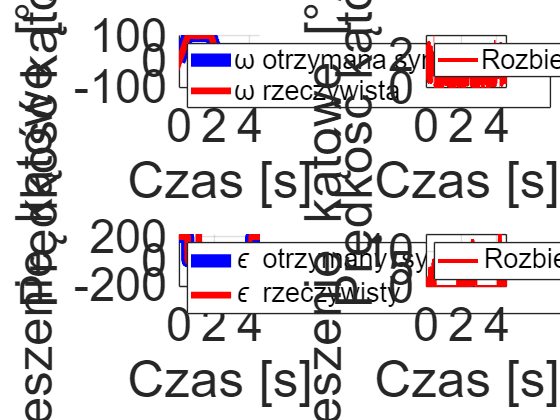

xlim([0 4.58]);
set(gca, 'FontSize', 35)

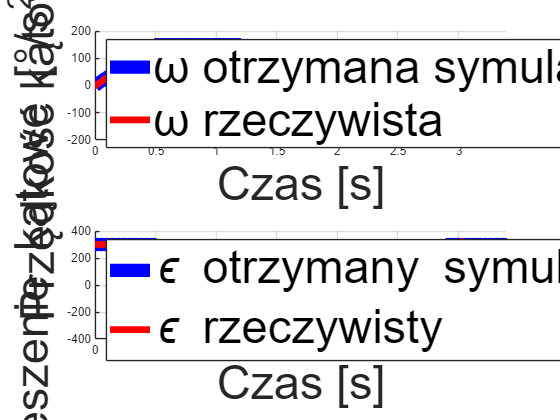

ur3 = loadrobot("universalUR3", "DataFormat", "row", "Gravity", [0 0 -9.81]);

v_max = deg2rad(150);
a_max = deg2rad(300);
dt = 0.01;

q_home = [-0, -90, 0, -90, 0, -0.000]*pi/180;
q_end  = [0, -90, 0, -90, 180, -0.000]*pi/180;

q_home = q_home(:); 
q_end = q_end(:);   

dq = abs(q_end - q_home);
t_total_joint = zeros(6,1);

for i = 1:6
    if dq(i) < 1e-4
        t_total_joint(i) = 0.5;
        continue;
    end
    t_acc = v_max / a_max;
    d_acc = 0.5 * a_max * t_acc^2;

    if dq(i) < 2*d_acc
        t_total_joint(i) = 2 * sqrt(dq(i) / a_max);
    else
        t_total_joint(i) = 2*t_acc + (dq(i) - 2*d_acc)/v_max;
    end
end

trajTime = max(t_total_joint);

nSteps = ceil(trajTime / dt);
T_vec = linspace(0, trajTime, nSteps);
[qt1, qd1, qdd1] = trapveltraj([q_home, q_end], nSteps, 'AccelTime', v_max/a_max, 'EndTime', trajTime);
[qt2, qd2, qdd2] = trapveltraj([q_end, q_home], nSteps, 'AccelTime', v_max/a_max, 'EndTime', trajTime);

q_traj = [qt1'; qt2'];
qd_traj = [qd1'; qd2'];
qdd_traj = [qdd1'; qdd2'];
T_full = linspace(0, 2*trajTime, 2*nSteps);

x = 1.69499;
[~, k] = min(abs(T_full - x));
qdd_traj(k,5) = qdd_traj(k-1,5);

TCP_pos = zeros(2*nSteps, 6);
for i = 1:2*nSteps
    T = getTransform(ur3, q_traj(i,:), 'tool0');
    TCP_pos(i,1:3) = tform2trvec(T);
    TCP_pos(i,4:6) = tform2eul(T);
end

TCP_vel = [zeros(1,6); diff(TCP_pos)/dt];
TCP_acc = [zeros(1,6); diff(TCP_vel)/dt];


M = csvread('3531_ums.csv', 1,0);

idxB = 1; idxE = length(M);

M = M(idxB:idxE, :);

VarNames = {'Id','SessionId','aX','aY','aZ','gX','gY','gZ','mX','mY','mZ','Thermometer','Barometer','Trigger'};
SDLData = cell2struct(num2cell(M, 1), VarNames,2);

figure;
subplot(2,1,1)
hold on;
plot(T_full, qd_traj(:,5)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-9.94), SDLData.gY, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 3.4]); 
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 35);
hold off;

subplot(2,1,2)
hold on;
plot(T_full, (qdd_traj(:,5))*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id(1:1100)/100-9.94), -SDLData.aY(1:1100), 'Color', [1 0 0], 'LineWidth', 5);
plot((SDLData.Id(1100:1250)/100-9.94), SDLData.aY(1100:1250), 'Color', [1 0 0], 'LineWidth', 5);
plot((SDLData.Id(1250:1400)/100-9.94), -SDLData.aY(1250:1400), 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 3.4]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 35);
hold off;


offset = 994;
omega_ref = qd_traj(:,5) * 180/pi;
omega_meas = SDLData.gY;

omega_meas_shifted = omega_meas(offset+1:end);

N_ref = length(omega_ref);
N_meas = length(omega_meas_shifted);
N = min(N_ref, N_meas);

omega_ref = omega_ref(1:N);
omega_meas_shifted = omega_meas_shifted(1:N);

I_omega = mean(abs(omega_ref - omega_meas_shifted));

fprintf('Wartość funkcji celu I(ω): %.6f [°/s]\n', I_omega);

Wartość funkcji celu I(ω): 1.214093 [°/s]



a_ref = qdd_traj(:,5) * 180/pi;
a_meas = -SDLData.aY;
a_meas(1100:1250) = -abs(a_meas(1100:1250));

a_meas_shifted = a_meas(offset:end);

N_ref = length(a_ref);
N_meas = length(a_meas_shifted);
N = min(N_ref, N_meas);

a_ref = a_ref(1:N);
a_meas_shifted = a_meas_shifted(1:N);

valid_idx = (a_meas_shifted ~= 0) & (a_ref ~= 0);

a_ref_valid = a_ref(valid_idx);
a_meas_valid = a_meas_shifted(valid_idx);

if isempty(a_ref_valid)
    warning('Brak próbek spełniających warunek a_ref ≠ 0 oraz a_meas ≠ 0.');
    I_acc = NaN;
else
    I_acc = mean(abs(a_ref_valid - a_meas_valid));
end

fprintf('Wartość funkcji celu I(a): %.6f [°/s^2]\n', I_acc);

Wartość funkcji celu I(a): 4.952881 [°/s^2]



I_omega_t = abs(omega_ref - omega_meas_shifted);

time_vec = T_full(1:N);

I_acc_t = abs(a_ref - a_meas_shifted);

I_acc_t_valid = I_acc_t;
I_acc_t_valid(~valid_idx) = NaN;

figure;
subplot(2,2,1)
hold on;
plot(T_full, qd_traj(:,5)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-offset/100), SDLData.gY, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 3.38]); 
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 20);
set(gca, 'FontSize', 35)
hold off;

subplot(2,2,3)
hold on;
plot(T_full, (qdd_traj(:,5))*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id(1:1100)/100-9.94), -SDLData.aY(1:1100), 'Color', [1 0 0], 'LineWidth', 5);
plot((SDLData.Id(1100:1250)/100-9.94), SDLData.aY(1100:1250), 'Color', [1 0 0], 'LineWidth', 5);
plot((SDLData.Id(1250:1400)/100-9.94), -SDLData.aY(1250:1400), 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 3.4]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 20);
set(gca, 'FontSize', 35)
hold off;

subplot(2,2,2)
plot(time_vec, I_omega_t, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 30);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
legend('Rozbieżność ω', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

set(gca, 'FontSize', 35)
xlim([0 3.38]);

subplot(2,2,4)
I_acc_plot = I_acc_t_valid;
I_acc_plot(isnan(I_acc_plot)) = 0;
plot(time_vec, I_acc_plot, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 35);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
legend('Rozbieżność \epsilon', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

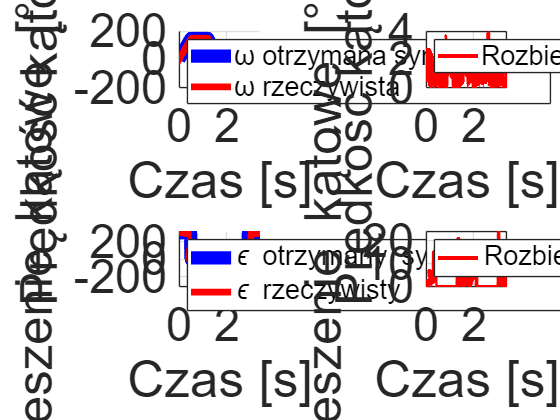

xlim([0 3.38]);
set(gca, 'FontSize', 35)